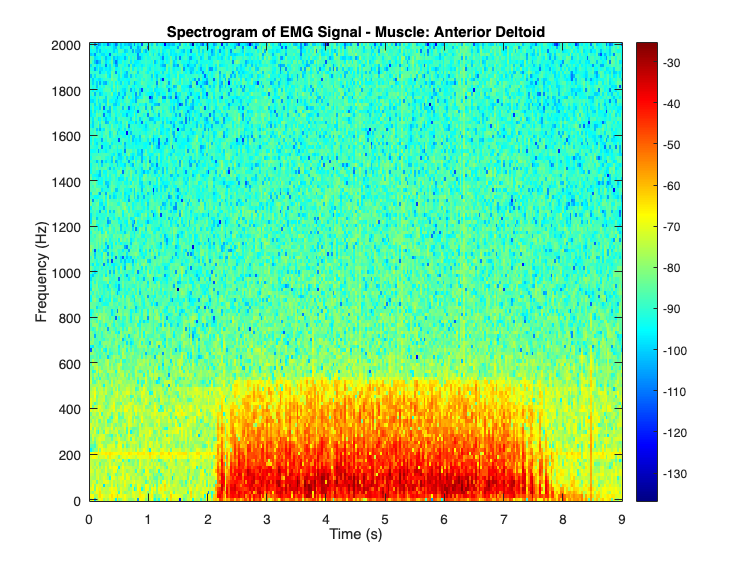

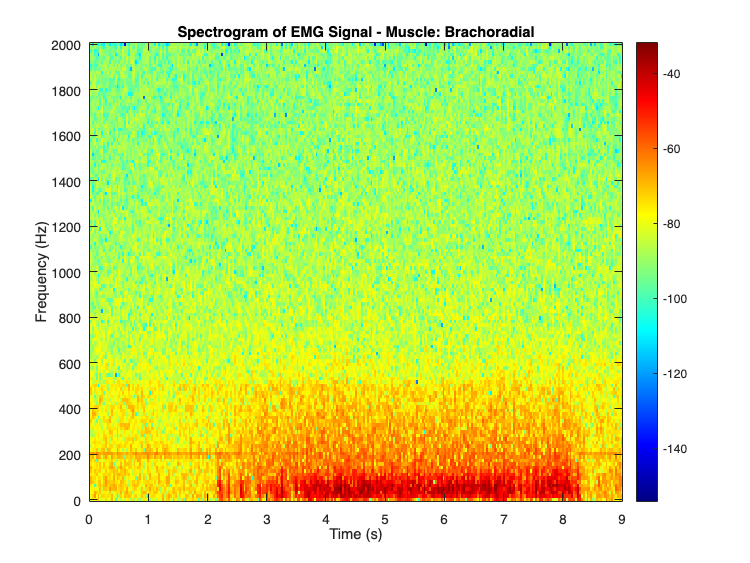

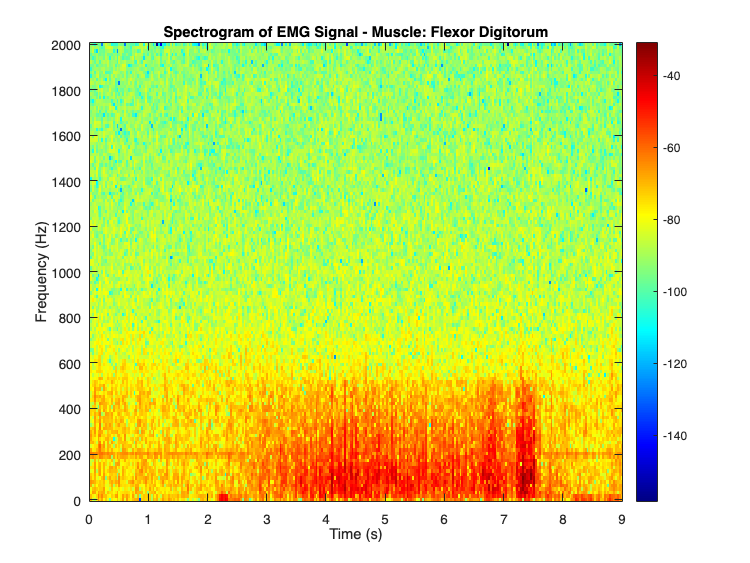

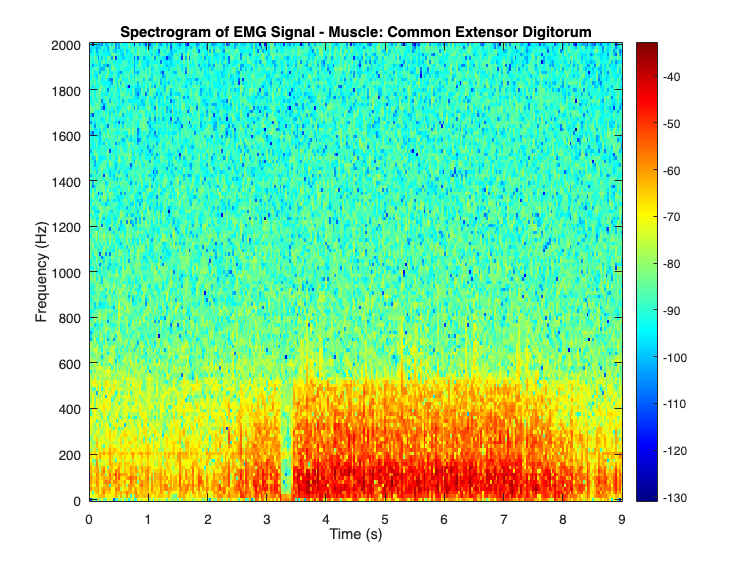

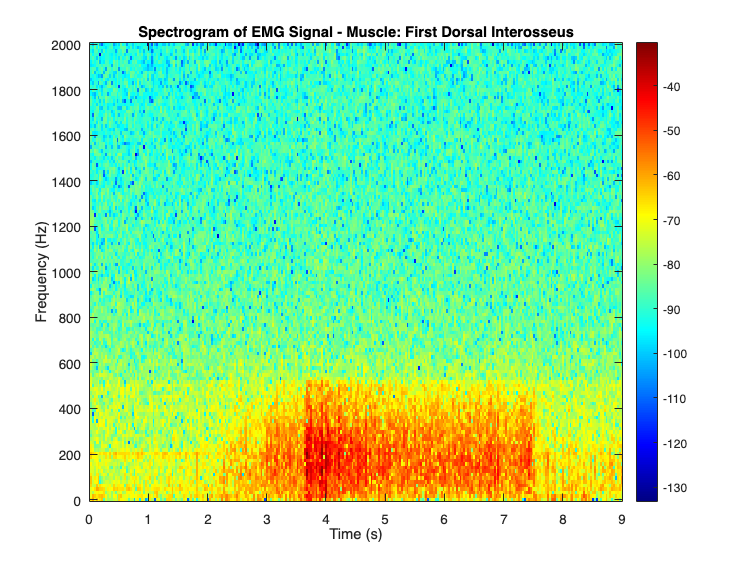

% Get the number of channels
num_channels = size(emg_data, 2);

% Set the time axis limits (0 to 9 seconds)
time_axis_limits = [0 9];

% Loop through each channel and create separate figures
for channel_number = 1:num_channels
    
    % Create a new figure for the current channel
    figure;
    
    % Get the corresponding muscle label from the muscle_labels array
    if channel_number <= length(muscle_labels)
        muscle_label = muscle_labels{channel_number};
    else
        muscle_label = 'Unknown';
    end
    
    % Parameters for the spectrogram
    window_length = 256; % You can adjust this window size as needed
    overlap_length = window_length / 2; % Overlap between windows
    fs = 1 / (emg_timestamps(2) - emg_timestamps(1));  % Sampling frequency
    
    % Create a spectrogram for the current EMG channel
    [S, F, T, P] = spectrogram(emg_data(:, channel_number), window_length, overlap_length, [], fs, 'yaxis');
    
    % Customize the color mapping for better visibility
    colormap jet; % Use the 'jet' colormap
    
    % Plot the spectrogram
    imagesc(T, F, 10 * log10(P)); % Use a logarithmic scale for better visualization
    set(gca, 'YDir', 'normal'); % Reverse the Y-axis direction
    
    % Set the time axis limits
    xlim(time_axis_limits);
    
    % Add a title and labels to the figure
    title(['Spectrogram of EMG Signal - Muscle: ' muscle_label]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    colorbar; % Add a color bar to indicate intensity
    
    % You can further customize the plot as needed
end